% Script para gerar a Resposta ao Degrau da velocidade do rastreador solar

clear; clc; close all;

% --- 1. Definição dos Parâmetros do Sistema ---
% Reutilizando os mesmos parâmetros do script anterior 
Ra = 1.0; La = 0.5; Kt = 0.01; Kb = 0.01;
J_total = 0.06; b_total = 0.12;

% --- 2. Criação da Função de Transferência de Velocidade G(s) ---
% G(s) = Omega(s)/Va(s) - Equação 16 do documento 
% É preferível analisar a resposta ao degrau da velocidade, pois ela se estabiliza 
numG = [Kt];
denG = [(La*J_total)   (Ra*J_total + La*b_total)   (Ra*b_total + Kt*Kb)];
G_motor_speed = tf(numG, denG);

disp('Função de Transferência de Velocidade G(s):');

Função de Transferência de Velocidade G(s):


printsys(numG, denG, 's');

 
num/den = 
 
              0.01
   --------------------------
   0.03 s^2 + 0.12 s + 0.1201


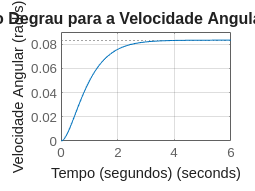


% --- 3. Geração e Análise da Resposta ao Degrau ---
figure('Name', 'Resposta ao Degrau da Velocidade');
step(G_motor_speed); % Comando para gerar a resposta ao degrau 
grid on;
title('Resposta ao Degrau para a Velocidade Angular (Malha Aberta)', 'FontSize', 12);
xlabel('Tempo (segundos)');
ylabel('Velocidade Angular (rad/s)');


% --- 4. Obtenção das Características da Resposta ---
speed_step_info = stepinfo(G_motor_speed); % 
disp('Características da Resposta ao Degrau da Velocidade:');

Características da Resposta ao Degrau da Velocidade:


disp(speed_step_info);

         RiseTime: 1.6774
    TransientTime: 2.9135
     SettlingTime: 2.9135
      SettlingMin: 0.0751
      SettlingMax: 0.0833
        Overshoot: 0
       Undershoot: 0
             Peak: 0.0833
         PeakTime: 5.9637

